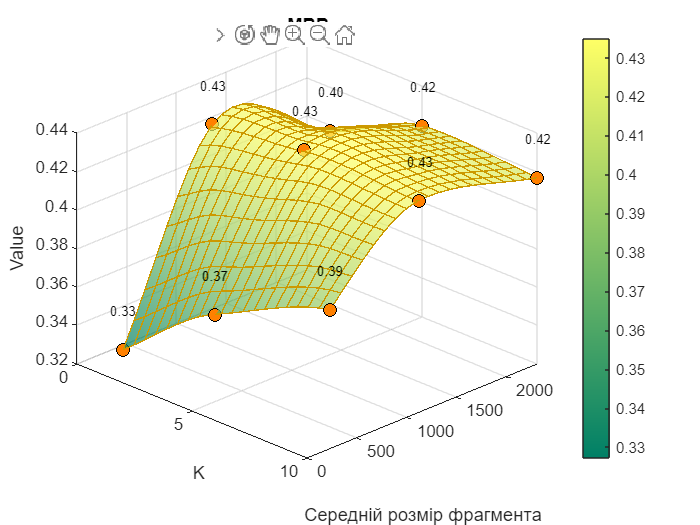

% -------------------------------------------------------------------------
% MATLAB: 3D-поверхня MRR із тією ж сіткою, підписами та осями, як у Precision@K
% -------------------------------------------------------------------------

% 1. Оригінальні дані для MRR
k_values    = [1, 5, 10];          % K                                                 
size_values = [227, 1129, 2312];   % Середній розмір фрагмента                       

Z2 = [ 0.3273, 0.3653, 0.3921;      % MRR
       0.4256, 0.4321, 0.4301;
       0.3970, 0.4192, 0.4167 ];

% 2. Дискретна сітка 3×3 для початкових точок
[K_orig, S_orig] = meshgrid(k_values, size_values);  % 3×3 :contentReference[oaicite:3]{index=3}

% 3. Та ж «щільна» сітка 20×20, що й для Precision@K
kq = linspace(min(k_values),   max(k_values),   20);   % 20 точок від 1 до 10       :contentReference[oaicite:4]{index=4}
sq = linspace(min(size_values), max(size_values), 20);  % 20 точок від 227 до 2312   :contentReference[oaicite:5]{index=5}
[Kq, Sq] = meshgrid(kq, sq);

% 4. Інтерполяція «cubic» для плавного вигину поверхні MRR
Z2_interp = griddata(K_orig, S_orig, Z2, Kq, Sq, 'cubic');  % C¹-сплайн через 9 точок 

% 5. Побудова MRR із усіма 9 початковими точками
figure;

% 5.1. Гладка поверхня MRR
hSurf = surf(Kq, Sq, Z2_interp, ...
     'FaceAlpha', 0.7, ...             % трохи прозорості
     'EdgeColor','none', ...           % без ребер заливки
     'FaceColor','interp');            % інтерполяція кольору за Z    
hold on;

% 5.2. Ребра поверхні (mesh) для фактури
hMesh = mesh(Kq, Sq, Z2_interp, ...
     'EdgeColor',[0.8, 0.6, 0], ...     % темно-золотисті ребра          :contentReference[oaicite:8]{index=8}
     'FaceColor','none', ...
     'LineWidth',0.8);                  % товщина ліній 0.8             

% 5.3. Наносимо початкові 9 точок (як у Precision@K)
hScatter = scatter3(K_orig(:), S_orig(:), Z2(:), ...
         60, ...                        % розмір маркера 60
         'filled', ...                  % маркер заповнений
         'MarkerFaceColor',[1, 0.5, 0],... % помаранчевий (RGB [1 0.5 0]) :contentReference[oaicite:10]{index=10}
         'MarkerEdgeColor','k');        % окантовка чорним                 :contentReference[oaicite:11]{index=11}

% 5.4. Підписи значень Z2 над кожною з 9 точок
for i = 1:numel(Z2)
    text(K_orig(i), S_orig(i), Z2(i) + 0.02, ...  % зсув по Z для читабельності
         sprintf('%.2f', Z2(i)), ...              % формат з двома знаками після коми
         'FontSize', 8, ...
         'HorizontalAlignment', 'center', ...
         'Color', 'k');                             % чорний колір тексту          :contentReference[oaicite:12]{index=12}
end

% 6. Підписи осей та заголовок
xlabel('K');                                          % назва осі X                      :contentReference[oaicite:13]{index=13}
ylabel('Середній розмір фрагмента');                   % назва осі Y                      :contentReference[oaicite:14]{index=14}
zlabel('Value');                                      % назва осі Z                      :contentReference[oaicite:15]{index=15}
title('MRR');                                         % заголовок                        :contentReference[oaicite:16]{index=16}

% 7. Колірна карта та легенда
colormap(summer);                                     % колірна карта summer (золот.-зел.) :contentReference[oaicite:17]{index=17}
colorbar;                                             % показати шкалу кольорів            :contentReference[oaicite:18]{index=18}

% 8. Кут огляду
view(45, 30);                                         % азимут 45°, елевейшн 30°           :contentReference[oaicite:19]{index=19}

hold off;